### Computing linear combinations of features 

Let's first use an artificial dataset to demonstrate what forward propagation does to our data. The example below uses a training dataset `X` with 20 observations and 3 predictor variables. We are also assuming that there is 1 activation node in the hidden layer. 

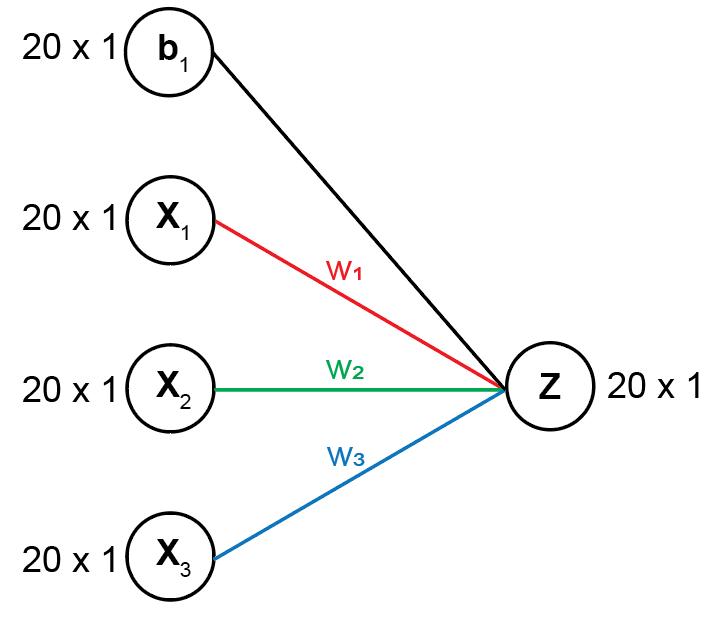

#### Analogy to linear regression

The formula to take a linear combination of predictors is shown below. The new features are stored in the variable `Z`.


$$Z=Xw^T +b$$


While this problem is slightly different from a linear regression problem in that we are solving for the output `Z` rather than using `X` and `Z` to estimate our coefficients, we actually have the same objective, and we're trying to estimate two parameters: 

- The **weights** ($w$), which is equivalent to the regression coefficients $\beta$

- The **bias** ($b$) values, which is equivalent to the intercept $\beta_0$. 

#### Impact of weights on the new feature `Z` generated by the neural network 

For now, let's see how the two parameters $w$ and $b$ affect the solution $Z$, and then plot the relationship between $X$ and $Z$. We'll take the linear combinations with 1 to 3 weights and biases of different values. 

% Initialize inputs using random numbers using a fixed random number generator (rng)
% for reproducibility
rng(2);
X = normrnd(0, 1, [20, 3])

X =    -0.1242    0.0125    1.4454
   -2.5415   -1.0163    0.0000
    0.2772   -0.1156    2.8467
   -0.1960   -0.7763   -0.3859
   -0.1962   -1.1398    0.1502
   -0.3057    0.3198   -0.3172
   -1.1289   -0.5715   -0.1628
    0.1942   -1.6300    0.8194
   -0.6071   -0.9364    0.0817
   -0.8284   -0.2786    1.9564


b = randn([20, 1])

b =     1.1527
    0.3926
    0.7993
   -1.9146
   -0.5855
    0.0593
   -0.5918
   -2.4356
    1.8796
   -0.1841


#### Solution using 1 weight vector

The following network using 1 weight value looks like the diagram below:

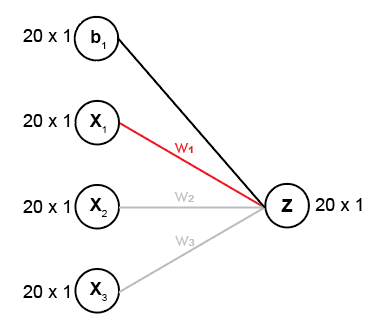

Which is equivalent to solving the following set of equations:


$$Z=X_1 w_1 +b$$


% Weight vectors
w = [1, 0, 0]

w =      1     0     0


Z1 = X * w' + b

Z1 =     1.0285
   -2.1489
    1.0765
   -2.1106
   -0.7817
   -0.2464
   -1.7207
   -2.2414
    1.2725
   -1.0125


Because we know $Z_2$ and $Z_3$ are equal to $b$, let's only plot the relationship between each predictor in $X$ and $Z_1$:

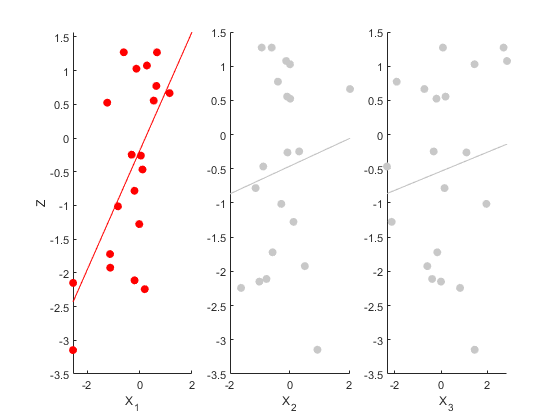

gray = [200,200,200]/255; 
subplot(1, 3, 1); scatter(X(:, 1), Z1, 'red', 'filled')
xlabel('X_{1}'); ylabel('Z');
set(lsline, 'color', 'r')

subplot(1, 3, 2)
scatter(X(:, 2), Z1, [], gray, 'filled')
xlabel('X_{2}'); lsline

subplot(1, 3, 3)
scatter(X(:, 3), Z1, [], gray, 'filled')
xlabel('X_{3}'); lsline

#### Solution using 2 weight vectors

If we include two weights, the network will look like the following diagram:

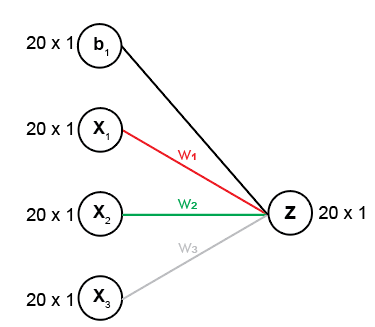

And the system of equations will look like the following:


$$Z=X_1 w_1 +X_2 w_2 +b$$


% Weight vectors
w = [1, 2, 0]

w =      1     2     0


As you can see, 

Z2 = X * w' + b

Z2 =     1.0535
   -4.1814
    0.8453
   -3.6632
   -3.0614
    0.3931
   -2.8636
   -5.5014
   -0.6003
   -1.5698


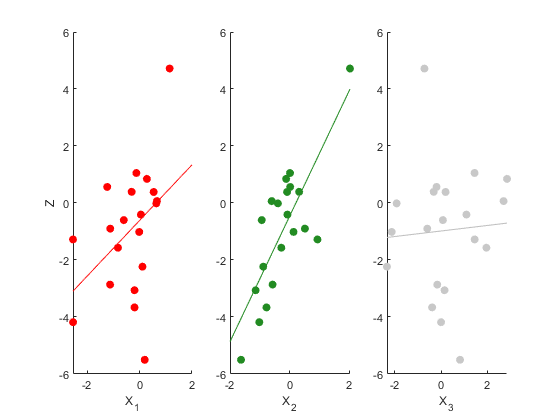

green = [34, 139, 34] ./ 255;
subplot(1, 3, 1); scatter(X(:, 1), Z2, 'red', 'filled')
xlabel('X_{1}'); ylabel('Z');
set(lsline, 'color', 'r')

subplot(1, 3, 2)
scatter(X(:, 2), Z2, [], green, 'filled')
xlabel('X_{2}'); set(lsline, 'color', green)

subplot(1, 3, 3)
scatter(X(:, 3), Z2, [], gray, 'filled')
xlabel('X_{3}'); lsline

#### Solution using 3 weight vectors

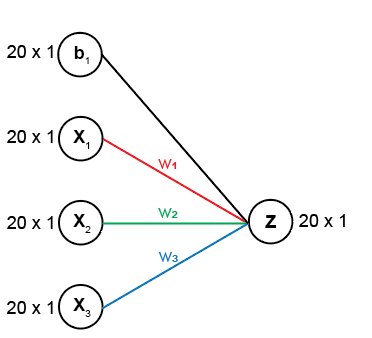

And the complete set of linear equations to solve will be:


$$Z=X_1 w_1 +X_2 w_2 +X_3 w_3 +b$$


% Weight vectors
w = [1, 2, -5];

As you can see, 

Z3 = X * w' + b

Z3 =    -6.1737
   -4.1815
  -13.3883
   -1.7339
   -3.8122
    1.9791
   -2.0497
   -9.5984
   -1.0088
  -11.3516


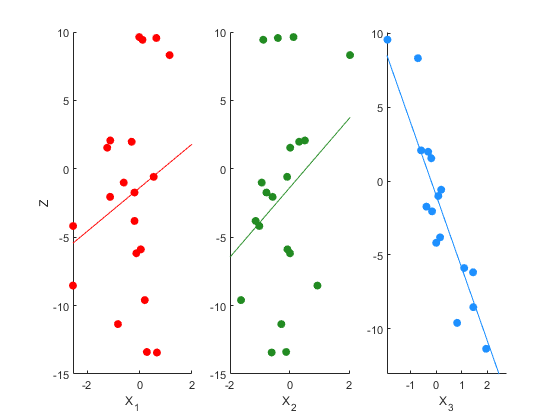

blue = [30, 144, 255] ./ 255;
subplot(1, 3, 1); scatter(X(:, 1), Z3, 'red', 'filled')
xlabel('X_{1}'); ylabel('Z');
set(lsline, 'color', 'r')

subplot(1, 3, 2)
scatter(X(:, 2), Z3, [], green, 'filled')
xlabel('X_{2}'); set(lsline, 'color', green)

subplot(1, 3, 3)
scatter(X(:, 3), Z3, [], blue, 'filled')
xlabel('X_{3}'); 
set(lsline, 'color', blue)

#### Overall impact of w on Z and key points:

figure;
h = boxplot([Z1, Z2, Z3], ...
    'Labels', {'Z1', 'Z2', 'Z3'}, ... 
    'PlotStyle', 'traditional')

h =     2.0031    9.0031   16.0031
    3.0031   10.0031   17.0031
    4.0031   11.0031   18.0031
    5.0031   12.0031   19.0031
    6.0031   13.0031   20.0031
    7.0031   14.0031   21.0035
    8.0031   15.0031   23.0040


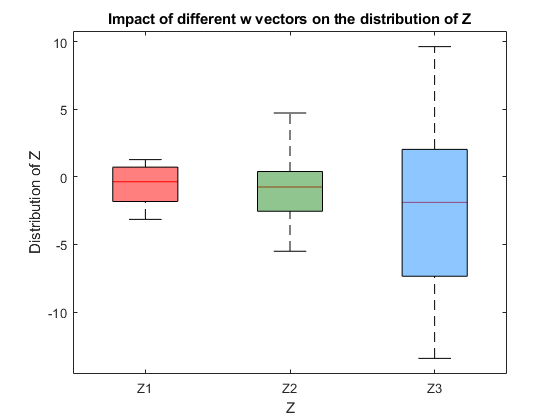

h = findobj(gca, 'Tag', 'Box'); 
color = {blue, green, 'r'};
for j = 1:length(h) 
    patch(get(h(j), 'XData'), ...
        get(h(j), 'YData'), ...
        color{j}, ...
        'FaceAlpha', 0.5);
end 
xlabel('Z'); ylabel('Distribution of Z');
title('Impact of different w vectors on the distribution of Z');

As you can see, different combinations of weights dramatically the final computed predictor `Z.` Thus, the weights are a really important parameter to tune in the model.

ans =   ConstantLine with properties:

    InterceptAxis: 'y'
            Value: 0.5000
            Color: [0.1500 0.1500 0.1500]
        LineStyle: '-'
        LineWidth: 0.5000
            Label: ''
      DisplayName: ''

  Show all properties


ans =   ConstantLine with properties:

    InterceptAxis: 'y'
            Value: 0.5000
            Color: [0.1500 0.1500 0.1500]
        LineStyle: '-'
        LineWidth: 0.5000
            Label: ''
      DisplayName: ''

  Show all properties


ans =   ConstantLine with properties:

    InterceptAxis: 'y'
            Value: 0.5000
            Color: [0.1500 0.1500 0.1500]
        LineStyle: '-'
        LineWidth: 0.5000
            Label: ''
      DisplayName: ''

  Show all properties


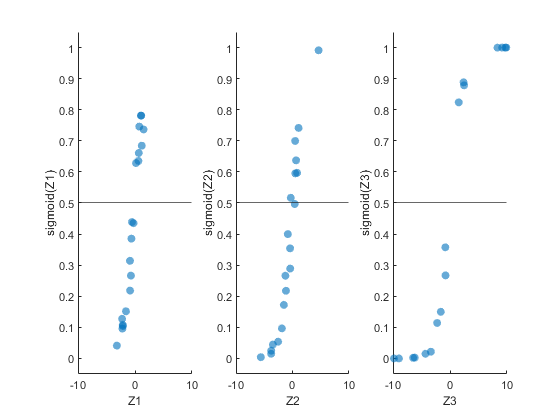

A = activationFnc(Z, 'Sigmoid');
for i = 1:size(Z, 2)
    subplot(1, 3, i)
    scatter(Z(:, i), A(:, i), ...
                'filled', 'o',  ...
                'MarkerFaceAlpha', 0.6, ...
                'jitter', 'on', ...
                'jitterAmount', 0.5);
            
    % Labeling parameters
    xlabel(strcat('Z', string(i))); ylabel(strcat('sigmoid(Z', string(i), ')'));
    ylim([-0.05, 1.05]); xlim([-10, 10]);
    %yline(0.5); % Draw decision boundary
end

figure; hold on;
plot(1:epoch, J(:, 1), 'color', 'r');
plot(1:epoch, J(:, 2), 'color', 'g');
legend('Malignant', 'Benign');
title('Cost with learning rate = 0.05');
xlabel('Number of epochs');
ylabel('Cost (J)');